# **Controls for parameter tuning**

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

## Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_thin_mask\extracted_arboreal_scans\2019-10-01_exp_1\2019-10-01_exp_1.mat')


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


# 1. Test the effect of subsampling data

## Test 1.1 : Test how the Kfold setting (for training) affect the prediction

range = 2:10; result_kfold = {};
for idx = 1:numel(range)  
    out = {};
    parfor iter = 1:10
        out{iter} = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'trigger','encoder'}, '', 'kfold', kfold_range(idx));
    end
    result_kfold{idx} = out;%cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', out, 'UniformOutput', false));
end

Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2367)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The model out-of-sample misclassification rate is 35.9%
The model out-of-sample misclassification rate is 29.5%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at pea

bar_chart(result_kfold, 'beh_type');

File: bar_chart.m Line: 28 Column: 117
Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

## Test 1.2 : Test how the Holdout setting affect the prediction

range = linspace(0.1:0.9,9); result_holdout = {};
for idx = 1:numel(range)  
    out = {};
    parfor iter = 1:10
        out{iter} = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'trigger','encoder'}, '', 'holdout', range(idx));
    end
    result_holdout{idx} = out;
end

Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2367)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The model out-of-sample misclassification rate is 37.4%
The model out-of-sample misclassification rate is 26.3%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at pea

Error using internal.stats.cvpartitionInMemoryImpl (line 132)
The number of observations must be a positive integer greater than one.

Error in cvpartition (line 175)
                cv.Impl = internal.stats.cvpartitionInMemoryImpl(varargin{:});

Error in 

bar_chart(result_holdout, 'beh_type');

## Test 1.3 : Test how good is the hyperparameter optimization

The model out-of-sample misclassification rate is 33.5%
The model out-of-sample misclassification rate is 29.6%
The model out-of-sample misclassification rate is 34.9%
The model out-of-sample misclassification rate is 32.5%
The model out-of-sample misclassification rate is 38.3%
The model out-of-sample misclassification rate is 31.8%
The model out-of-sample misclassification rate is 38%
The model out-of-sample misclassification rate is 29.3%
The model out-of-sample misclassification rate is 39.2%
The model out-of-sample misclassification rate is 30.4%
The model out-of-sample misclassification rate is 37.9%
The model out-of-sample misclassification rate is 30.4%
The model out-of-sample misclassification rate is 38.5%
The model out-of-sample misclassification rate is 30.9%
The model out-of-sample misclassification rate is 28.3%
The model out-of-sample misclassification rate is 30.4%
The model out-of-sample misclassification rate is 32.4%
The model out-of-sample misclassification rate is 

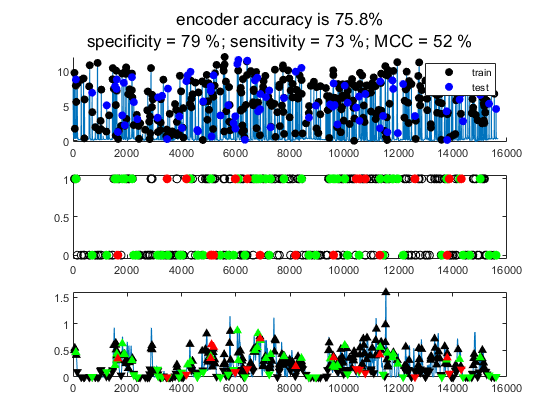

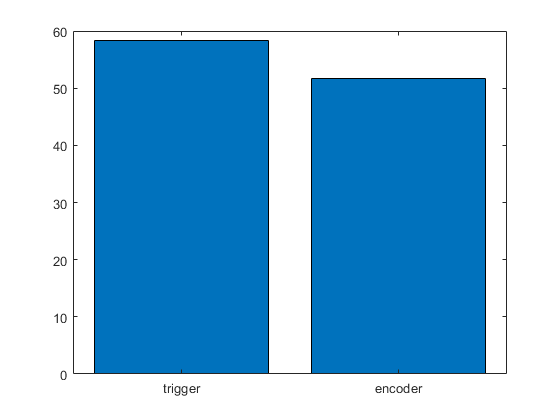

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       1 | Best   |      0.2133 |    0.083438 |      0.2133 |     0.21332 |       274.68 |       816.53 |
|    2 |       1 | Accept |     0.48837 |     0.13607 |      0.2133 |     0.21332 |       283.01 |     0.010677 |
|    3 |       1 | Accept |     0.48837 |     0.12384 |      0.2133 |     0.21332 |     0.072297 |    0.0036147 |
|    4 |       1 | Accept |     0.48837 |    0.087478 |      0.2133 |     0.21332 |      0.29748 |       197.23 |
|  

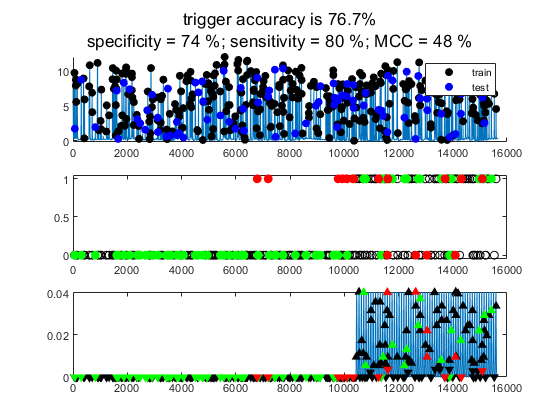

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       1 | Accept |     0.43557 |    0.095083 |     0.24897 |     0.41315 |       95.511 |       990.72 |
|    2 |       1 | Accept |     0.47846 |    0.088323 |     0.24897 |     0.41315 |    0.0045372 |       540.94 |
|    3 |       1 | Accept |     0.47846 |     0.13574 |     0.24897 |     0.41315 |      0.86835 |     0.031147 |
|    4 |       1 | Accept |     0.47846 |     0.12808 |     0.24897 |     0.41315 |       994.04 |     0.028516 |
|  

Error using bayesoptim.BayesoptParallel/get.ParPool (line 28)
'UseParallel' is true, but there is no current parallel pool and auto-creation of pools is disabled.

Error in bayesoptim.BayesoptParallel (line 39)
            pool = this.ParPool;

Error in 

range = [false, true, true];
method = ['', 'native', 'manual'];
result = {};
for idx = 1:numel(range)  
    out = {};
    for iter = 1:10
        out{iter} = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'trigger','encoder'}, '', 'optimize_hyper', range(idx), 'optimization_method', method(idx));
    end
    result{idx} = out;
end

bar_chart(result, 'beh_type');











plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
